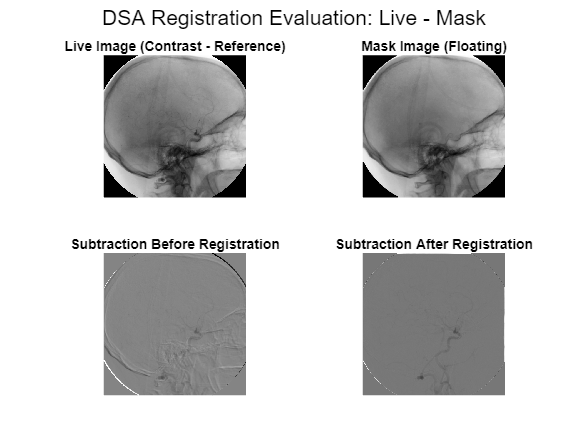

%% Clear workspace and close figures
clear; close all; clc;

%% Read the images
% Contrast image (live_new) is the reference image.
live = imread('live_new.tif');  
% Mask image (mask_new) is the floating image.
mask = imread('mask_new.tif');

% Convert to grayscale if necessary
if size(live,3) == 3
    live = rgb2gray(live);
end
if size(mask,3) == 3
    mask = rgb2gray(mask);
end

% Convert images to double precision for processing
live = im2double(live);
mask = im2double(mask);

%% Compute the Subtracted Image WITHOUT Registration
% Always subtract the mask from the live image (live - mask) so that the vessels appear dark.
diffBefore = live - mask;

%% Perform Non-Rigid Registration
% numIterations = [5000, 400, 200];
numIterations = [50, 20, 5];
AFS = 3;

[~, maskReg] = imregdemons(mask, live, numIterations, 'AccumulatedFieldSmoothing', AFS);

%% Compute the Subtracted Image WITH Registration
diffAfter = live - maskReg;

%% Display the Evaluation Figures
% The evaluation includes:
%   1. The original live (contrast) image (reference)
%   2. The original mask image (floating)
%   3. The subtracted image BEFORE registration (live - mask)
%   4. The subtracted image AFTER registration (live - registered mask)
figure('Name','DSA Registration Evaluation','NumberTitle','off');

subplot(2,2,1);
imshow(live, []);
title('Live Image (Contrast - Reference)');

subplot(2,2,2);
imshow(mask, []);
title('Mask Image (Floating)');

subplot(2,2,3);
imshow(diffBefore, []);
title('Subtraction Before Registration');

subplot(2,2,4);
imshow(diffAfter, []);
title('Subtraction After Registration');

sgtitle('DSA Registration Evaluation: Live - Mask');

%% Save the Output Images
% Since subtraction images might have negative values, we use mat2gray to scale them to [0,1]
imwrite(live, 'live_new.png');
imwrite(mask, 'mask_new.png');
imwrite(mat2gray(diffBefore), 'diff_before_registration.png');
imwrite(mat2gray(diffAfter), 'diff_after_registration.png');
imwrite(mat2gray(maskReg), 'mask_registered.png');

% Optionally, save the evaluation figure as an image
saveas(gcf, 'DSA_Registration_Evaluation4.png');